## Technical Prerequisites

This lab is concerned with homing and trajectory tracking and does not consider obstacles, therefore all assignments simulate the robot with the empty world map.

As an empty map lacks any environmental objects that a range sensor may perceive a proper localization with the $\textit{Adaptive Monte Carlo Localization}$ (AMCL) is infeasible. Therefore, the pose estimation of the $\texttt{/odom}$ relies on odometry only. In a second terminal, start RViz using

The goal pose is specified by the user in RViz with the $\texttt{2D Nav Goal}$ button and is published on the topic $\texttt{/move\_base\_simple/goal}$. Notice that the goal pose in$\texttt{/move\_base\_simple/goal}$ is published w.r.t. the $\texttt{odom}$ rather than the $\texttt{map}$ frame. Thus the representation of goal pose is consistent with the robots pose from odometry.

## Homing with Goal Point

Homing considers the current position and heading of the robot relative to a desired position and calculates a motion command based on their difference. The turn rate $$\omega$ $regulates the heading error towards the goal point $$\alpha$$ to zero, the forward velocity is proportional to the Euclidean distance $$\rho$$ to the goal.

The objective of the first part of the lab is to implement a simple homing control law that guides the robot  to a fixed goal position $$x_g, y_g$$. Either implement the solution with a while loop that explicitly receive messages or more elegantly with a callback subscriber that automatically responds to messages. The helper functions $\texttt{OdometryMsg2Pose}$, $\texttt{PoseStampedMsg2Pose}$ and $\texttt{Pose2PoseStampedMsg}$ map the message to a pose $\texttt{[x, y, theta]}$ and vice versa. For the following tasks, you have to instantiate a variable with the ROS transformation tree in the beginning of your main script:

clear all; clc;
rosshutdown
rosinit('http://ubuntu:11311/')

Initializing global node /matlab_global_node_07406 with NodeURI http://192.168.2.111:55340/


tftree = rostf;

1) Define a subscriber $\texttt{odomSub}$that subscribes to the$ \texttt{/odom}$ topic to receive the robot pose. Define a subscriber $\texttt{navGoalSub}$ that subscribes to the $\texttt{/move\_base\_simple/goal}$ topic in order to receive the user selected navigation goal from RViz. Define a publisher $\texttt{velPub}$ for publishing velocity commands on the topic $\texttt{/cmd\_vel}$. 

odomSub = rossubscriber('/odom');
navGoalSub = rossubscriber('/move_base_simple/goal');
velPub = rospublisher('/cmd_vel');

2) Implement a function $\texttt{[rho, alpha] = poseErrorTf(navGoalMsg, tfTree)}$ that calculates the pose error in polar coordinates $$\rho, \alpha$ $from the pose messages $\texttt{navGoalMsg}$. Determine the goal pose in robocentric coordinates by transforming the entity $\texttt{navGoalMsg}$ specified w.r.t. $\texttt{odom} $ frame to the $\texttt{'base\_link'}$ with the function $\texttt{transform}$. Obtain the resulting goal pose $$x_g^{(r)}, y_g^{(r)}, \theta_g^{(r)}$$ using the helper function $$\texttt{PoseStampedMsg2Pose} $$ . The goal position error becomes


$$\rho = \sqrt{{x_g^{(r)}}^2 + {y_g^{(r)}}^2}$$



$$\alpha = \mathrm{atan2} (y_g^{(r)}, x_g^{(r)})$$


This transformation can be realized using the Matlab built-in function$\texttt{[alpha, rho] = cart2pol(x, y)}$.

3) Implement a function$\texttt{[v, omega ] = homingControl(rho, alpha)}$  that realizes a simple proportional controller to regulate the heading error $$\alpha$$ and the translational error $$\rho$$ to zero:


$$v = k_\rho \rho \\$$



$$\omega = k_\alpha \alpha$$


Include a control signal saturation that limits the commanded forward velocity to $$v_{max}$$ and turn rate to $$\omega \in [\omega_{min},\omega_{max}]$$. Reasonable values for $$k_\rho$$ and $$k_\alpha$$ are $$0.5$$ and $$1$$ respectively.

4) Integrate the two functions into the while loop of the main program code. Retrieve the $\texttt{navGoalMsg}$ from the corresponding (callback) subscriber. Determine the pose error from the messages with $\texttt{poseErrorTf}$ and map the pose error onto the motion command with  $\texttt{homingControl}$. Publish the commanded turn rate and forward velocity on the $\texttt{/cmd\_vel}$topic and message type $\texttt{geometry\_msg/Twist}$.

close all

rate = 10;
rateObj = robotics.Rate(rate);

rho = inf;
goalRadius = 0.2;

disp('Specify 2D Nav Goal...');

Specify 2D Nav Goal...


navGoalMsg = receive(navGoalSub, 30);

% variables to record the evolution of the robot
time = [];
rho_data = [];
alpha_data = [];
posesX = [];
posesY = [];
posesTheta = [];

rateObj.reset;  % reset time at the beginning of inner loop
while (rho > goalRadius)   
   % calculate pose error from odom and navgoal
   [rho, alpha] = poseErrorTf(navGoalMsg, tftree);
   
   % calculate velocity command from pose error
   [v, omega] = homingControl(rho, alpha);
   
   velMsg = rosmessage('geometry_msgs/Twist');
   velMsg.Linear.X = v;
   velMsg.Angular.Z = omega;
   send(velPub,velMsg);
   
   % store rho, alpha, x, y, theta
   odomMsg = odomSub.LatestMessage;
   [x, y, theta] = OdometryMsg2Pose(odomMsg);
   
   time = [time rateObj.TotalElapsedTime];
   rho_data = [rho_data rho];
   alpha_data = [alpha_data alpha];
   posesX = [posesX x];
   posesY = [posesY y];
   posesTheta = [posesTheta theta];
   
   waitfor(rateObj);
end 
disp('Goal reached!');

Goal reached!


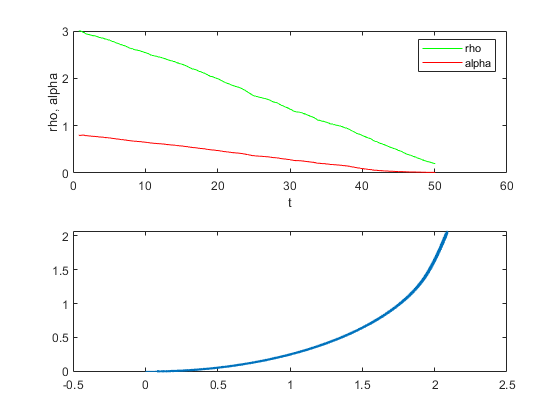

velMsg.Linear.X = 0;
velMsg.Angular.Z = 0;
send(velPub,velMsg);

% Task 5 
subplot(2,1,1)
plot(time, rho_data, 'g', time, alpha_data, 'r');
xlabel('t')
ylabel('rho, alpha')
legend('rho', 'alpha')
subplot(2,1,2)
quiver(posesX, posesY, cos(posesTheta), sin(posesTheta))

5) Test your code by commanding the robot to navigation goals in RViz. Record and plot the evolution of the pose error $$[\rho, \alpha]$$ over time. Record and plot the robot path $$[x, y, \theta]$$ using $\texttt{quiver(posesX, posesY, cos(posesTheta), sin(posesTheta))}$.

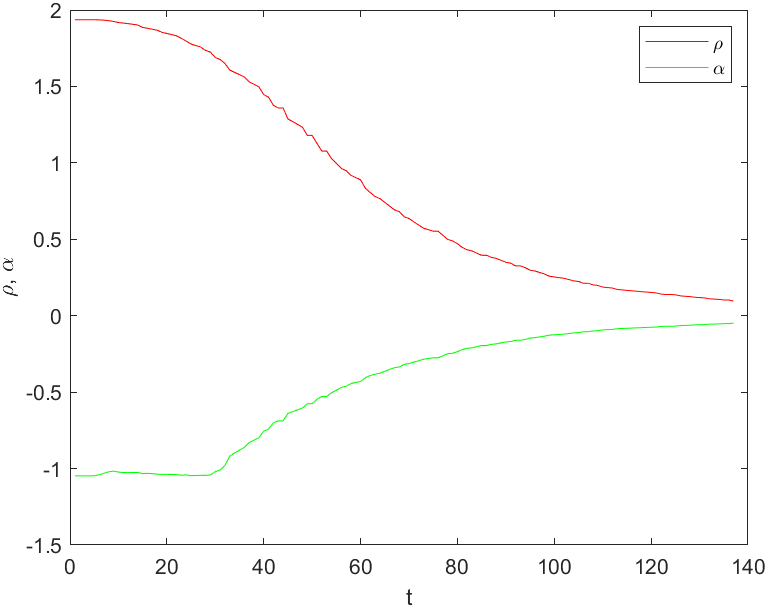

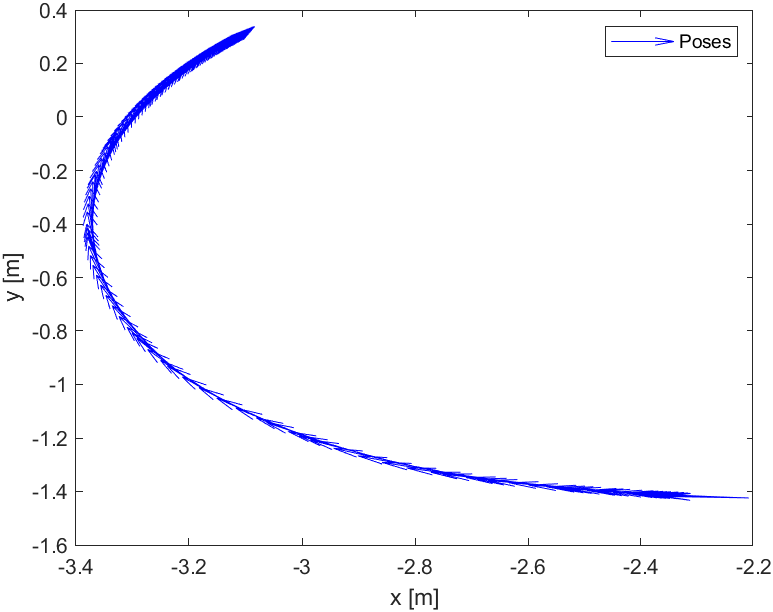

6) (Optional) Implement the same homing controller with a callback subscriber on the $\texttt{/odom}$ topic.The callback function obtains references to the publisher of the navigation goal and velocity command. The handle object $\texttt{poseErrorObject}$ of class $\texttt{PoseErrorHandle} $(m-file provided in Moodle) has the properties $\texttt{rho}$, $\texttt{alpha}$, $\texttt{phi}$, $\texttt{deltay}$. The properties $\texttt{poseErrorObject.rho}$ and $\texttt{poseErrorObject.alpha}$ are assigned within the callback function. The two remaining properties $\texttt{phi}$, $\texttt{deltay}$ will become relevant later in the context of homing with goal orientation and pure pursuit path tracking. The handle object $\texttt{poseErrorObject}$ enables it to share the pose error data between the callback function and the main program. Reception of pose messages, calculation of pose error and velocity commands and publishing of velocity commands is delegated to the callback function. The main program merely monitors the translational error $\texttt{poseErrorObject.rho}$ to determine whether the goal point has been reached upon which it clears the callback subscriber.

close all;

% variables to record the evolution of the robot
time = [];
rho_data = [];
alpha_data = [];
posesX = [];
posesY = [];
posesTheta = [];

rate = 10;
rateObj=robotics.Rate(rate);

poseErrorObject = PoseErrorHandle;
poseErrorObject.rho = inf;
goalRadius = 0.2;

disp('Specify 2D Nav Goal...');

Specify 2D Nav Goal...


navGoalMsg = receive(navGoalSub, 30);

odomSubCallback = rossubscriber('/odom',{@odomHomingCallback,navGoalSub,...
	velPub, poseErrorObject, tftree});

rateObj.reset;  % reset time at the beginning of inner loop
while (poseErrorObject.rho > goalRadius)   
    odomMsg = odomSub.LatestMessage;
    [x, y, theta] = OdometryMsg2Pose(odomMsg);
    
    time = [time rateObj.TotalElapsedTime];
    rho_data = [rho_data poseErrorObject.rho];
    alpha_data = [alpha_data poseErrorObject.alpha];
    posesX = [posesX x];
    posesY = [posesY y];
    posesTheta = [posesTheta theta];
    waitfor(rateObj);
end 
disp('Goal reached!');

Goal reached!


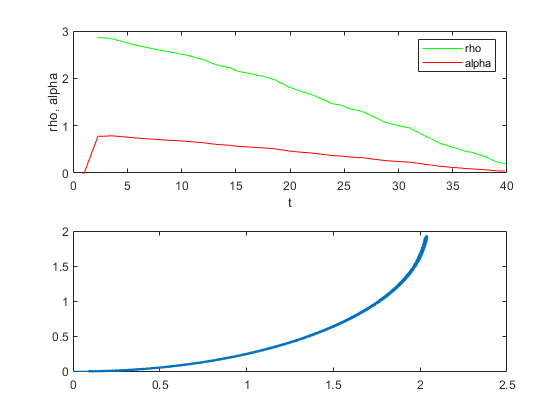

velMsg = rosmessage('geometry_msgs/Twist');
velMsg.Linear.X = 0;
velMsg.Angular.Z = 0;
send(velPub,velMsg);
clear odomSubCallback;

subplot(2,1,1)
plot(time, rho_data, 'g', time, alpha_data, 'r');
xlabel('t')
ylabel('rho, alpha')
legend('rho', 'alpha')
subplot(2,1,2)
quiver(posesX, posesY, cos(posesTheta), sin(posesTheta))

## Trajectory Tracking and Homing with Goal Pose

7) Augment the function $\texttt{[rho, alpha, phi] = poseErrorTf(navGoalMsg, tftree)}$such that it additionally outputs the angle $$\phi$$ between the x-axis $$X_R$$ of the robocentric frame and the x-axis $$X_G$$ associated with the goal pose. 

8) Implement the control law for exponential stabilization w.r.t. the new coordinates $$\rho,\phi,\alpha$$. For that purpose augment the original controller function by an additional input parameter $\texttt{[ v, omega ] = homingControl(rho, alpha, phi)}$. Make sure to determine the correct sign of the linear velocity $$v$$ according to whether $$\alpha \in I_1$$ or $$\alpha \in I_2$$. For $$\alpha \in I_2$$ substitute $$v$$ with $$-v$$ and remap $$\alpha$$ to $$I_1$$.

9) Select proper settings for the controller gains $$k_\rho, k_\phi, k_\alpha$$ . Test the controller for reference poses commanded with the RViz navigation button. Record and plot the evolution of the pose error $$[\rho, \alpha, \phi]$$ over time as shown in the figure. Record and plot the robot poses $$[x, y, \theta]$$.

close all;

% variables to record the evolution of the robot
time = [];
rho_data = [];
alpha_data = [];
phi_data = [];
posesX = [];
posesY = [];
posesTheta = [];

rate = 10;
rateObj=robotics.Rate(rate);

rho = inf;
goalRadius = 0.2;
goalOrientation = deg2rad(5);

disp('Specify 2D Nav Goal...');

Specify 2D Nav Goal...


navGoalMsg = receive(navGoalSub, 30);

rateObj.reset;  % reset time at the beginning of inner loop
while (rho > goalRadius || abs(phi) > goalOrientation)   
    [rho, alpha, phi] = poseErrorTf(navGoalMsg, tftree);
    [v, omega] = homingControl(rho, alpha, phi);
    
    velMsg = rosmessage('geometry_msgs/Twist');
    velMsg.Linear.X = v;
    velMsg.Angular.Z = omega;
    send(velPub,velMsg);
    
    odomMsg = odomSub.LatestMessage;
    [x, y, theta] = OdometryMsg2Pose(odomMsg);
    
    time = [time rateObj.TotalElapsedTime];
    rho_data = [rho_data rho];
    alpha_data = [alpha_data alpha];
    phi_data = [phi_data phi];
    
    posesX = [posesX x];
    posesY = [posesY y];
    posesTheta = [posesTheta theta];
    waitfor(rateObj);
end 
disp('Goal reached!');

Goal reached!


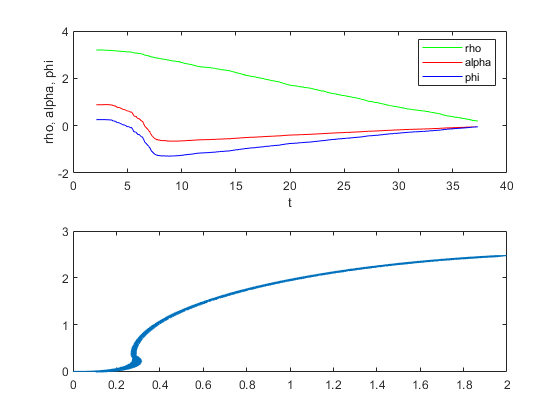

velMsg.Linear.X = 0;
velMsg.Angular.Z = 0;
send(velPub,velMsg);

subplot(2,1,1)
plot(time, rho_data, 'g', time, alpha_data, 'r', time, phi_data, 'b');
xlabel('t')
ylabel('rho, alpha, phi')
legend('rho', 'alpha', 'phi')
subplot(2,1,2)
quiver(posesX, posesY, cos(posesTheta), sin(posesTheta))

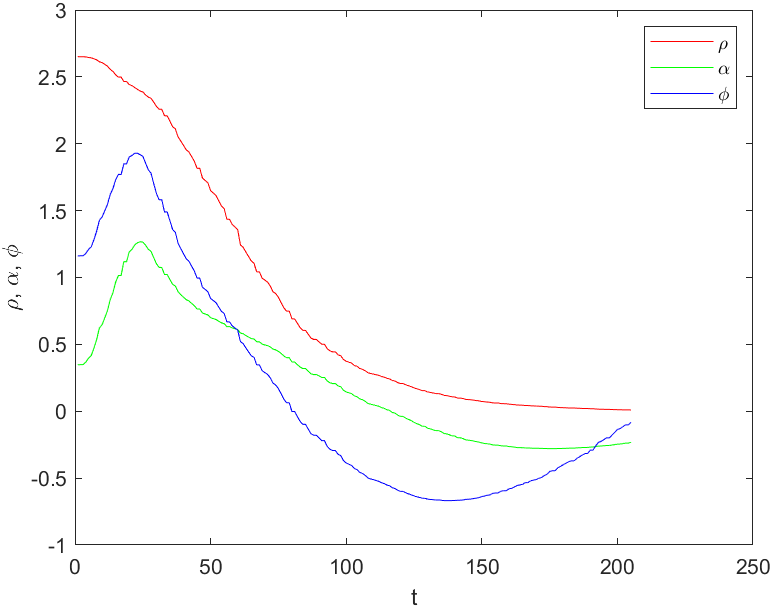

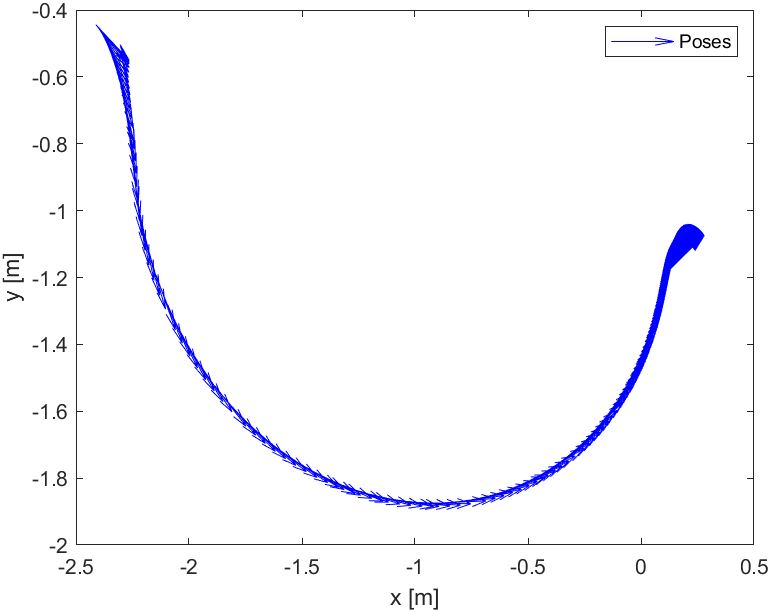

10) Replace the RVIZ navigation goal publisher by your own publisher. The navigation goal subscriber $\texttt{navGoalSub}$ subscribes to the topic $\texttt{'/waypoint'}$ rather than the RVIZ navigation goal. In that way the communication structure encapsulates the generation and maintenance of navigation goals from the navigation controller. Define a $$n\times3$$ array $\texttt{waypoints}$ as a $\textbf{global} $ variable that will contain a sequence of reference poses to be traversed  in the order $1$ to $n$. Instantiate a callback subscriber that monitors the robot pose. The callback function is provided as a helper function. It merely publishes the first waypoint in the list as $\texttt{'geometry\_msgs/PoseStamped'}$ message on the topic $\texttt{'/waypoint'}$. It removes the current waypoint if the distance between the current robot pose and the waypoint is less than the goal radius. It stops publishing navigation goals once the list of waypoints is empty.

11) The while loop termination condition in the main program changes. The while loop terminates as the list of waypoints is empty.

12)Test your controller in reaching the central goal pose $$[x_r, y_r, \theta_r] =[0,0,\pi/2]$$ starting from  a set of initial poses $$[x, y, \theta] =\{[1 , 0, 0], [1/\sqrt{2} , 1/\sqrt{2}, 0], [0 , 1, 0], \ldots, [1/\sqrt{2}, -1/\sqrt{2}, 0]  \}$$ located on the unit circle. For that purpose define a sequence of waypoints that alternates between the start poses on the unit circle and the central goal pose. 

close all;

% reduced the rate to avoid overruns due to computational overload
rate = 5;
rateObj = robotics.Rate(rate);

% define waypoints, publisher and subscriber
n = 16;
global waypoints 
waypoints = ones(n,3);

unit_circle = [1 0 0; 1/sqrt(2) 1/sqrt(2) 0; 0 1 0; -1/sqrt(2) 1/sqrt(2) 0; -1 0 0;...
    -1/sqrt(2) -1/sqrt(2) 0; 0 -1 0; 1/sqrt(2) -1/sqrt(2) 0];
central_pose = [0 0 pi/2];

for i = 1:n/2
    waypoints(2*i-1,:) = unit_circle(i,:);
    waypoints(2*i,:) = central_pose;
end

odomMsg = odomSub.LatestMessage;
wayPointPub = rospublisher('/waypoint', 'geometry_msgs/PoseStamped');
wayPointSub = rossubscriber('/waypoint');

odomSubWayPointCallback = rossubscriber('/odom', {@odomWayPointCallback, wayPointPub});

wayPointMsg = wayPointSub.LatestMessage;
while isempty(wayPointMsg)
    wayPointMsg = receive(wayPointSub,10);
end

rateObj.reset;
while ~isempty(waypoints)
    wayPointMsg = wayPointSub.LatestMessage;
    if ~isempty(wayPointMsg)
        [rho, alpha, phi] = poseErrorTf(wayPointMsg, tftree);
        [v, omega] = homingControl(rho, alpha, phi);
        
        velMsg = rosmessage('geometry_msgs/Twist');
        velMsg.Linear.X = v;
        velMsg.Angular.Z = omega;
        send(velPub,velMsg);
        
        waitfor(rateObj);
    end
end 
disp('Goal reached!');
velMsg.Linear.X = 0;
velMsg.Angular.Z = 0;
send(velPub,velMsg);
clear odomWayPointSubCallback

## Pure Pursuit Tracking Algorithm

13) Following the same strategy as for the $\texttt{'waypoint'}$ publisher, implement and instantiate a publisher $\texttt{lookAheadPointPub} $ that publishes the current lookahead point as a navigation goal topic $\texttt{'/lookaheadpoint'}$ to which $\texttt{navGoalSub}$ subscribes. Instantiate a callback subscriber that monitors the robot pose. A callback function is provided as a helper function. It publishes the current look ahead point as$\texttt{'geometry\_msgs/PoseStamped'}$ message on the topic $\texttt{'/lookaheadpoint'}$. It automatically transitions to the next segment and removes waypoints that are located on segments that the robot already completed. It stops publishing navigation goals once the list of waypoints is empty.

14) Augment the function $\texttt{poseErrorTf}$ such that it provides the lateral displacement $$y_g^{(r)}$$  in robocentric coordinates as an additional output parameter:$\texttt{[rho, alpha, phi, deltay] = poseErrorTf(navGoalMsg, tftree)}$

15) Implement the pure pursuit controller for a constant forward velocity $$v=0.5$$. Modify the function $\texttt{[ v, omega ] = homingControl(rho, alpha, phi, deltay)}$to implement the curvature based control law.

16) Test your pure pursuit controller for the sequence of waypoints: $\texttt{waypoints=[0 0 0; 4 4 0; 8 0 0; 12 4 0; 16 0 0]}$

17) (Optional) Investigate the effect of the lookahead distance on the tracking performance. Obtain a statistics of the average lateral offset of the robot from the straight line path as a function of the lookahead distance. 

close all

vr = [];
omegar = [];
time = [];

% reduced the rate to avoid overruns due to computational overload
rate = 2;
rateObj=robotics.Rate(rate);

% define waypoints, publisher and subscriber
global waypoints;
global nextPathPointIdx;
waypoints = [0 0 0; 4 4 0; 8 0 0; 12 4 0; 16 0 0];

lookAheadPointPub = rospublisher('/lookaheadpoint',  'geometry_msgs/PoseStamped');
lookAheadPointSub = rossubscriber('/lookaheadpoint');

odomSubLookAheadPointCallback = rossubscriber('/odom', {@odomLookAheadPointCallback, lookAheadPointPub});

lookAheadPointMsg = lookAheadPointSub.LatestMessage;
while isempty(lookAheadPointMsg)
    lookAheadPointMsg = receive(lookAheadPointSub, 10);
end

rateObj.reset;  % reset time at the beginning of inner loop
while ~isempty(waypoints)  
    lookAheadPointMsg = lookAheadPointSub.LatestMessage;
    [xp, yp, thetap] = PoseStampedMsg2Pose( lookAheadPointMsg );
    
    [rho, alpha, phi, deltay] = poseErrorTf(lookAheadPointMsg, tftree);
    [v, omega] = homingControl(rho, alpha, phi, deltay);
    
%     vr = [vr v];
%     omegar = [omegar omega];
%     time = [time rateObj.TotalElapsedTime];
    
    velMsg = rosmessage('geometry_msgs/Twist');
    velMsg.Linear.X = v;
    velMsg.Angular.Z = omega;
    send(velPub,velMsg);
    
    odomMsg = odomSub.LatestMessage;
    [x, y, theta] = OdometryMsg2Pose(odomMsg);
    
%     subplot(3,1,1)
%     nxtp = waypoints(nextPathPointIdx, 1:2);
%     quiver(x, y, cos(theta), sin(theta), 'b');
%     hold on;
%     quiver(xp, yp, cos(thetap), sin(thetap), 'g');
%     if ~isempty(nxtp)
%         plot(nxtp(1),nxtp(2), 'r-o');
%     end
%     title('Status')
%     subplot(3,1,2)
%     plot(time, vr);
%     title('V')
%     subplot(3,1,3)
%     plot(time, omegar);
%     title('OMEGA')
    
    waitfor(rateObj);  
end 
disp('Goal reached!');
velMsg.Linear.X = 0;
velMsg.Angular.Z = 0;
send(velPub,velMsg);
clear odomLookAheadPointSubCallback

# Functions that have to be implemented

function [rho, alpha, phi, deltay] = poseErrorTf(navGoalMsg, tftree)
    sourceFrame = 'odom';
    targetFrame = 'base_link';

    if canTransform(tftree, targetFrame, sourceFrame)
        poseErrorMsg = transform(tftree, targetFrame, navGoalMsg);
        [xr_g, yr_g, thetar_g] = PoseStampedMsg2Pose(poseErrorMsg);
        [alpha, rho] = cart2pol(xr_g, yr_g);
        %alpha = -alpha;
        phi = thetar_g;
        deltay = yr_g;
    end
end

function [v, omega] = homingControl(rho, alpha, phi, deltay)
    switch nargin
        case 2
            vmax = 0.2; omegamax = 0.1; omegamin = -0.1;
            k_rho = 0.5;
            k_alpha = 1;
            v = min(vmax, k_rho*rho);
            omega = max(omegamin, min(omegamax, k_alpha*alpha));
        case 3          
            vmax = 0.35;
            omegamax = pi/2; 
            omegamin = -pi/2; 
            k_rho = 2; k_alpha = 8; k_phi = -4; 
            
            v = min(vmax, k_rho*rho);
            if ((alpha > -pi) && (alpha <= -pi/2) || (alpha > pi/2) && (alpha <= pi))
                v = -v;
                if alpha < -pi/2
                    alpha = alpha + pi;
                elseif alpha > pi/2
                    alpha = alpha - pi;
                end
            end
            omega = max(omegamin, min(omegamax, k_alpha*alpha + k_phi*phi));
        case 4
            v = 0.5;
            omegamax = pi/2;
            omegamin = -pi/2; 
            omega = max(omegamin, min(omegamax, 2*deltay*v/(rho^2)));
    end    
end

function odomHomingCallback(~, ~, navGoalSub, velPub, poseErrorObject, tftree)
    navgoalmsg = navGoalSub.LatestMessage;
    sourceFrame = navgoalmsg.Header.FrameId;
    targetFrame = 'base_link';

    waitForTransform(tftree, targetFrame, sourceFrame);
    if canTransform(tftree, targetFrame, sourceFrame)
        poseErrorMsg = transform(tftree, targetFrame, navgoalmsg);
        [xr_g, yr_g, phi] = PoseStampedMsg2Pose(poseErrorMsg);
        [alpha, rho] = cart2pol(xr_g, yr_g);
        %alpha = -alpha;
        
        poseErrorObject.alpha = alpha;
        poseErrorObject.rho = rho;
        poseErrorObject.deltay = yr_g;
        poseErrorObject.phi = phi;
        [v, omega] = homingControl(rho, alpha);
        
        velMsg = rosmessage(velPub);
        velMsg.Linear.X = v;
        velMsg.Angular.Z = omega;
        send(velPub,velMsg);
    end       
end


# Helper Functions

function [ x, y, theta ] = OdometryMsg2Pose( odomMsg )
    % convert odometry message to vector
    x=odomMsg.Pose.Pose.Position.X;
    y=odomMsg.Pose.Pose.Position.Y;
    eul=quat2eul([odomMsg.Pose.Pose.Orientation.W odomMsg.Pose.Pose.Orientation.X  odomMsg.Pose.Pose.Orientation.Y odomMsg.Pose.Pose.Orientation.Z]);
    theta=eul(1);
end

function [ poseMsg ] = Pose2PoseStampedMsg( x, y, theta )
    % convert vector to pose stamped message 
    poseMsg=rosmessage('geometry_msgs/PoseStamped');
    poseMsg.Pose.Position.X=x;
    poseMsg.Pose.Position.Y=y;
    poseMsg.Pose.Position.Z=0;
    q=eul2quat([theta, 0, 0]);
    poseMsg.Pose.Orientation.W=q(1);
    poseMsg.Pose.Orientation.X=q(2);
    poseMsg.Pose.Orientation.Y=q(3);
    poseMsg.Pose.Orientation.Z=q(4);
end

function [ x, y, theta ] = PoseStampedMsg2Pose( poseMsg )
    % convert odometry message to vector
    x=poseMsg.Pose.Position.X;
    y=poseMsg.Pose.Position.Y;
    eul=quat2eul([poseMsg.Pose.Orientation.W poseMsg.Pose.Orientation.X  poseMsg.Pose.Orientation.Y poseMsg.Pose.Orientation.Z]);
    theta=eul(1);
end

function [] = odomWayPointCallback( ~, odomMsg, wayPointPub )
    % Callback function for waypoint on topic odom
    % wayPointPub : publisher for waypoint navigation goals
    
    persistent once
    
    global waypoints
    goalRadius = 0.2;
    goalOrientation = deg2rad(5);
    
    
    if isempty(once) && ~isempty(waypoints)
        once=1;
        disp(['first waypoint ', mat2str(waypoints(1,:),2)]);
    end
    
    if ~isempty(waypoints)
        
        % Transform odom position into map frame
        [x,y,theta] = OdometryMsg2Pose(odomMsg);
       
        % generate geometry_msgs/PoseTimeStamped Message
        % Publish goal in odom frame
        navGoalMsg=Pose2PoseStampedMsg(waypoints(1,1), waypoints(1,2), waypoints(1,3));
        navGoalMsg.Header.FrameId = 'odom';
        send(wayPointPub,navGoalMsg);
        
        
        %[x, y, t] = PoseStampedMsg2Pose(odomPoseMapMsg);
        if norm([x-waypoints(1,1), y-waypoints(1,2)]) < goalRadius && abs(angdiff(waypoints(1,3), theta)) < goalOrientation
            if size(waypoints,1)>1
                disp(['waypoint ', mat2str(waypoints(1,:),2), ' cleared.']);
                disp(['next waypoint ', mat2str(waypoints(2,:),2)]);
            else
                disp(['final waypoint ', mat2str(waypoints(1,:),2), ' cleared.']);
            end
            waypoints=waypoints(2:end,:);
        end
    end
end

function [xp, yp, phip, nextPathPointIdx, previousPathPointCleared] = lookaheadpoint(x, y, waypoints, lookaheaddistance)
%·lookaheadpoint - Calculates the next lookaheadpoint
%·========================================================================
%
%  [xp, yp] = lookaheadpoint(x, y, waypoints, lookaheaddistance)
%
%  Description:
%    Calculates the next goalpoint based on the current position [x,y] and
%    the path waypoints defined in waypoints with the distance defined in
%    lookaheaddistance.
%
%  Input:
%    x: Current X-Position
%    y: Current Y-Position
%    waypoints: n x 2 array of waypoints
%    lookaheaddistance: Distance of the lookaheadpoint to the robot
%
%  Output:
%    xp: X-Position of the lookaheadpoint
%	 yp: Y-Position of the lookaheadpoint
%    phip: direction of the line segment on which lookaheadpoint is located
%
%  Known Bugs:
%	  - 
%
%
%  Authors:
%	 Christian Wissing
%
%  See also
%
%  Copyright (c) 2014 RST, Technische Universität Dortmund, Germany
%                     www.rst.e-technik.tu-dortmund.de
%
%%·=======================================================================
%#codegen

if size(waypoints,2) ~= 2
    error('Dimension of waypoints should be n by 2!');
end

% Number of waypoints
nWaypoints = size(waypoints,1);

% Actual position
pAct = [x, y];

% Find closest point on the path
projectedPoint = [];
normDirectionVec = [];
minDist = 99999;
nextPathPointIdx = 1;
for i_point = 1:nWaypoints-1
    
    % Project point on the segment
    p1 = waypoints(i_point,:);
    p2 = waypoints(i_point + 1,:);
    
    % Direction Vector
    dir = p2 - p1;
    l = norm(dir);
    
    if l == 0
        % Waypoints p1 and p2 are equal
        continue;
    end
    
    % Projection
    t = max([0, min([1, (pAct - p1)*dir'/(l^2)])]);
    pp = p1 + t * dir;
    
    dist = norm(pp-pAct);
    
    if dist < minDist
        minDist = dist;
        projectedPoint = pp;
        normDirectionVec = dir./l;
        nextPathPointIdx = i_point + 1;
    end    
end


% Check distance to next waypoint
dist2WP = norm((projectedPoint - waypoints(nextPathPointIdx,:)));
if dist2WP < lookaheaddistance
    % The lookahead point is on the consecutive segment
    previousPathPointCleared=0;
    % Check for end of path
    if nextPathPointIdx == nWaypoints
        xp = waypoints(nWaypoints, 1);
        yp = waypoints(nWaypoints, 2);
        phip = 0;
        return;
    end

    % Substract distance to next wp
    ldist = lookaheaddistance - dist2WP;
    % New projected point is the consecutive wp
    projectedPoint = waypoints(nextPathPointIdx,:);
    % New direction vector
    normDirectionVec = waypoints(nextPathPointIdx + 1,:) - waypoints(nextPathPointIdx,:);
    normDirectionVec = normDirectionVec./norm(normDirectionVec);
else
    % The lookahead point is on the actual segment
    previousPathPointCleared=1;
    ldist = lookaheaddistance;
end

% Calculate lookahead point
lp = projectedPoint + normDirectionVec * ldist;

xp = lp(1);
yp = lp(2);

[phip, rho] = cart2pol(normDirectionVec(1),normDirectionVec(2));
% Last line used to be: [rho, phip] = cart2pol(normDirectionVec(1),normDirectionVec(2));
end

function [] = odomLookAheadPointCallback( ~, odomMsg, lookAheadPointPub, lookaheaddistance)
    % Callback function for look ahead point on topic odom
    % wayPointPub : publisher for waypoint navigation goals
    
    persistent first_waypoint_reached
    
    global waypoints
    global waypointcleared;
    global nextPathPointIdx;
    
    goalRadius = 0.2;
    
    if nargin < 4
        lookaheaddistance=1.0;
    end
    
    % Transform odom position into map frame
    [xOdom,yOdom,~] = OdometryMsg2Pose(odomMsg);
    
    if isempty(first_waypoint_reached) && ~isempty(waypoints)
        
        disp(['first waypoint ', mat2str(waypoints(1,:),2)]);
        
        navGoalMsg=Pose2PoseStampedMsg(waypoints(1, 1), waypoints(1, 2), waypoints(1, 3));
        navGoalMsg.Header.FrameId = 'odom';
       	send(lookAheadPointPub,navGoalMsg);
        
        if norm([xOdom-waypoints(1,1), yOdom-waypoints(1,2)]) < goalRadius
            first_waypoint_reached=1;
        end
        
    elseif ~isempty(waypoints)
        
        % calculate look ahead point
        [x, y, phi, nextPathPointIdx]=lookaheadpoint(xOdom, yOdom, waypoints(:,1:2), lookaheaddistance);
        
    	% generate geometry_msgs/PoseTimeStamped Message in the map frame
        navGoalMsg=Pose2PoseStampedMsg(x, y, phi);
        navGoalMsg.Header.FrameId = 'odom';
       	send(lookAheadPointPub, navGoalMsg);
    
        % Disp current waypoint
        %disp(['Next waypoint: ', mat2str(waypoints(nextPathPointIdx, :))]);
        
        %disp(['Current lookaheadpoint: ', mat2str(x), ' ', mat2str(y), ' ' , mat2str(phi)]) % my addition for debugging
        
        % Check if final waypoint is reached
        if norm([xOdom-waypoints(end,1), yOdom-waypoints(end,2)]) < goalRadius && nextPathPointIdx >= size(waypoints, 1)
            disp(['final waypoint ', mat2str(waypoints(end,:),2), ' cleared.']);
            waypoints=[];
            waypointcleared=1;
        end
    end
end